Initialise N agents

% define the number of agents
N = 4;

% define the maximum X
xMax = 20;

% length of one time step
dt = 0.01;

% how long the simulation will run
T = 10;

% initialise the position of each agent
agents = zeros(T/dt, N+1);
agents(:, 1) = dt:dt:T;
agents(1, 2:N+1) = randperm(xMax, N);
centroid = mean(agents(1, 2:N+1));

Laplacian for a single path

% --------------------------------
% define the adjacency matrix
A = [[0, 1, 0, 0];
     [0, 0, 1, 0];
     [0, 1, 1, 1];
     [1, 0, 0, 0]];

% define the laplacian matrix
D = diag(sum(A,2));
L = D-A;
% --------------------------------

The Simulation

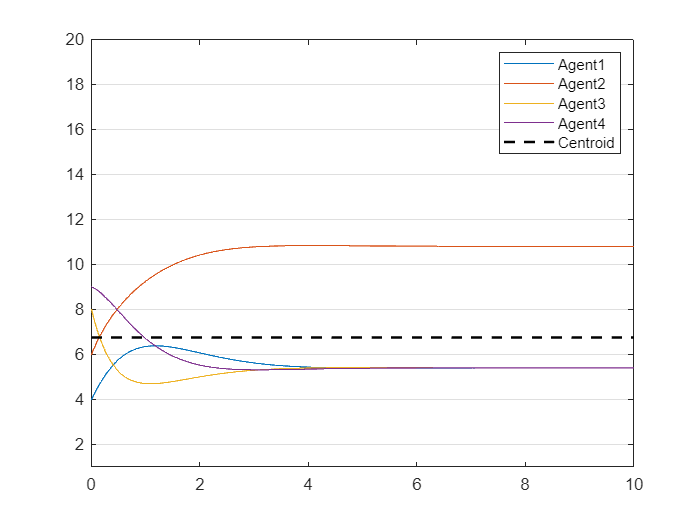

ans = 1

for t = 2*dt:dt:T
    idx = cast(t/dt, "uint32");
    agents(idx, 2:N+1) = update_agents(agents(idx-1, 2:N+1), dt, L);
end 

plot(agents(:, 1), agents(:, 2:N+1));
hold on
plot(agents(:, 1), mean(agents(:, 2:N+1), 2), 'k--', 'LineWidth', 1.5);
legend('Agent1', 'Agent2', 'Agent3', 'Agent4', 'Centroid')
set(gca,"XGrid","off","YGrid","on");
ylim(gca,[1,xMax]);

norm(velocities(:,i))

ans = 2.6226